## Task 0 :Uploading the audio file and getting its data

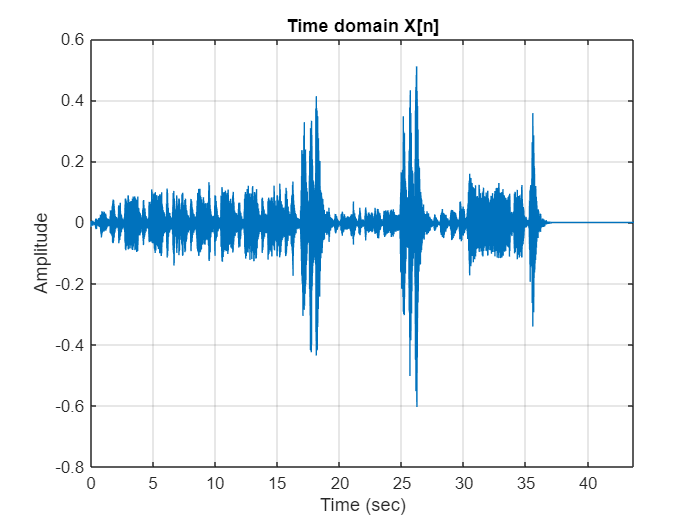

[xn,fs] = audioread('sample_audio_file.wav');
% convert from stero to mono 
xn = mean(xn,2);
N = length(xn);
% axis of drawing 
t = linspace(0, N/fs ,N);
% divided by fs or N ? 
xf = abs(fft(xn)) / N;
%xf = xf(1:N/2);
f = linspace(0, fs ,N);

figure
plot(t,xn)
grid on
title('Time domain X[n]')
xlabel('Time (sec)')
ylabel('Amplitude')
xlim([0, N/fs])

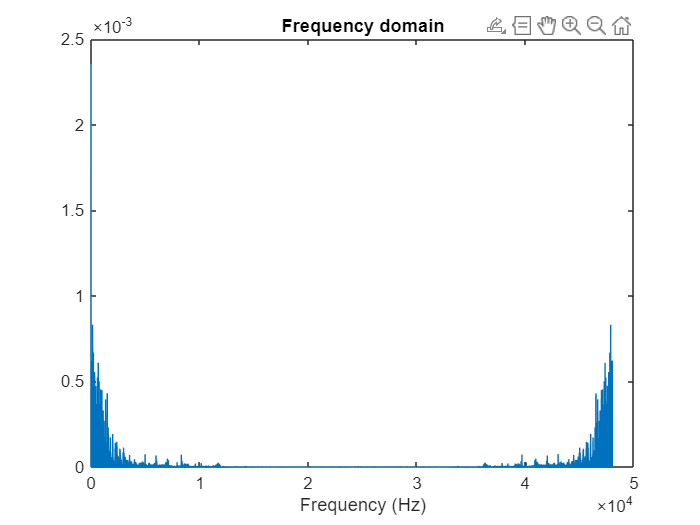

figure
plot(f,xf)
title('Frequency domain')
xlabel('Frequency (Hz)')

## Task 0 : Calcualation of the total energy in Time

Et = sum(xn.^2)

Et = 2.0186e+03

Ef = sum((abs(xf).^2)) * N 

Ef = 2.0186e+03